%% First check if L4 rates match neuron numbers
if length(Fr_MFinv) == 3*PixNum
rE = (Fr_MFinv(1:PixNum) + Fr_MFinv(PixNum+1:2*PixNum))/2; 
rI = Fr_MFinv(2*PixNum+1:3*PixNum); % f_EnI in s^-1, but here we use ms^-1
rE(rE<=0) = 0; rI(rI<0) = 0;
else
    error('L4 FRs dont match!')
end
%% Setup input and record
T = LIFSimuT*2; % in ms. Default: 20*1e3 ms
T1s = 1e3;
tt = 0:dt:T;
t1 = 0:dt:T1s;
SampleProp = 19/20; % last half time for meanV
DroptInd = floor(length(tt)*(1-SampleProp));
% L4 input determination: Assume all Poisson
% Can be optimized in the future, but let's make var correct for now
L4EInputNow = [C_EE_Pixel_Us*rE*(1-p_EEFail); 
               C_IE_Pixel_Us*rE             ]/1000;   
L4IInputNow = [C_EI_Pixel_Us*rI             ; 
               C_II_Pixel_Us*rI             ]/1000;   
L4Pix_EventsEU  = PoissonInputForNetwork(2*PixNum,L4EInputNow,LIFSimuT*TimeFrac,dt); % E to everyone
L4Pix_EventsIU  = PoissonInputForNetwork(2*PixNum,L4IInputNow,LIFSimuT*TimeFrac,dt); % I to everyone           
% Adjust Phase variant LGN
% Note: For LGN, I did the same scaling stuff for network simulation, so
% keep it for now.
tMod = T1s/LGNFreq; MaxOnPhase = tMod/2;
OnOffPhase = floor(mod(t1,tMod)/MaxOnPhase);
OnOffPhasePix = zeros(size(lgnEPix_Events));
OnOffPhasePix(:,OnOffPhase == 0) = repmat(lambda_EOff_Pixel, 1, sum(OnOffPhase == 0));
OnOffPhasePix(:,OnOffPhase == 1) = repmat(lambda_EOn_Pixel, 1, sum(OnOffPhase == 1));
OnOffMulp = OnOffPhasePix./repmat(lambda_E_Pixel,1,length(t1));
OnOffPhase(end) = [];
% Leakage
gL = [gL_E*ones(size(rE)); gL_I*ones(size(rI))];
% Initialize records
sumVOn = zeros(2*PixNum, 1);
sumVOff = zeros(2*PixNum, 1);
VNanOnCount = zeros(2*PixNum, 1);
VNanOffCount = zeros(2*PixNum, 1);
vt = zeros(2*PixNum, 1);
%% Evolve single neurons
RefTimer = zeros(2*PixNum, 1); 
vRecordNum = 0;
mVEon = zeros(PixNum,floor(T/T1s));
mVEoff = zeros(PixNum,floor(T/T1s));
mVI = zeros(PixNum,floor(T/T1s));
%% Can precompute all Gs...
for tInd = 1:length(tt)-1
    % First, Get input matrices from series
    InpWin = T1s; FrameNum = floor(InpWin/dt);
    FrameInd = mod(tInd, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    
    % When sample from Gs, GAMPA and GNMDA should use same time frame;
    if FrameInd == 1 % if the first frame, recompute input mats
        vRecord = zeros(length(vt),FrameNum);
        lgnEPix_Events = lgnEPix_Events(:,randperm(length(t1))); lgnIPix_Events = lgnIPix_Events(:,randperm(length(t1)));
        AmbEPix_Events = AmbEPix_Events(:,randperm(length(t1))); AmbIPix_Events = AmbIPix_Events(:,randperm(length(t1)));
        L6EPix_Events = L6EPix_Events(:,randperm(length(t1)));   L6IPix_Events = L6IPix_Events(:,randperm(length(t1)));
        L4Pix_EventsEU = L4Pix_EventsEU(:,randperm(length(t1))); L4Pix_EventsIU = L4Pix_EventsIU(:,randperm(length(t1)));
        % Incorporate L4 and other input
        EampaInp = single(full(S_Elgn * (lgnEPix_Events + lambda_E_Pixel*dt*LGNCurInp).*OnOffMulp ...
                             + S_amb  *  AmbEPix_Events ...
                             + S_EL6  * (L6EPix_Events  + L6E_Pixel*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnIPix_Events+ lambda_I_Pixel*dt*LGNCurInp) ...
                             + S_amb  *  AmbIPix_Events ...
                             + S_IL6  * (L6IPix_Events  + L6I_Pixel*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * (L6EPix_Events  + L6E_Pixel*dt*L6CurInp) * rhoE_nmda)); %
        InmdaInp = single(full(S_IL6  * (L6IPix_Events  + L6I_Pixel*dt*L6CurInp) * rhoI_nmda));
        L4InputfEampa = single(full( [S_EE * L4Pix_EventsEU(1:PixNum,:)          * rhoE_ampa;
                                      S_IE * L4Pix_EventsEU(PixNum+1:2*PixNum,:) * rhoI_ampa] ));
        L4InputfEnmda = single(full( [S_EE * L4Pix_EventsEU(1:PixNum,:)          * rhoE_nmda;
                                      S_IE * L4Pix_EventsEU(PixNum+1:2*PixNum,:) * rhoI_nmda] ));
        L4InputfI     = single(full( [S_EI * L4Pix_EventsIU(1:PixNum,:);
                                      S_II * L4Pix_EventsIU(PixNum+1:2*PixNum,:)] ));
        %% Precompute All Conductances: Speed up by ifft/fft
        winAMPA = 0:dt:tau_ampa_D*5;
        winNMDA = 0:dt:tau_nmda_D*5;
        winGABA = 0:dt:tau_gaba_D*5;
        KerAMPA = 1/(tau_ampa_D-tau_ampa_R) * (exp(-winAMPA/tau_ampa_D) - exp(-winAMPA/tau_ampa_R));
        KerNMDA = 1/(tau_nmda_D-tau_nmda_R) * (exp(-winNMDA/tau_nmda_D) - exp(-winNMDA/tau_nmda_R));
        KerGABA = 1/(tau_gaba_D-tau_gaba_R) * (exp(-winGABA/tau_gaba_D) - exp(-winGABA/tau_gaba_R));
        KerAMPA = KerAMPA / (sum(KerAMPA)*dt);
        KerNMDA = KerNMDA / (sum(KerNMDA)*dt);
        KerGABA = KerGABA / (sum(KerGABA)*dt);
        n = size(EampaInp,2);
        GAMPA = ifft(fft(([EampaInp; IampaInp] + L4InputfEampa)',n) .* repmat(fft(KerAMPA',n),1,2*PixNum))';
        GNMDA = ifft(fft(([EnmdaInp; InmdaInp] + L4InputfEnmda)',n) .* repmat(fft(KerNMDA',n),1,2*PixNum))';
        GGABA = ifft(fft(L4InputfI',n)                              .* repmat(fft(KerGABA',n),1,2*PixNum))';
        GE = GAMPA + GNMDA; GI = GGABA;
        GEU = GE;  
        GIU = GI; 
        vRecordNum = vRecordNum + 1;
    end
    
    % Firstly, refrectory neurons get out if timer reachs t_ref
    RefTimer(isnan(vt)) = RefTimer(isnan(vt)) + dt;
    vt(RefTimer>=tau_ref) = 0;
    RefTimer(RefTimer>=tau_ref) = 0;
    
    ov  = vt + dt*(-gL.*vt - GEU(:,FrameInd).*(vt-Ve) - GIU(:,FrameInd).*(vt-Vi));
    ov(ov>=1) = nan;
    vRecord(:,FrameInd) = ov;
    
    if FrameInd == FrameNum
        mVEon(:,vRecordNum) = nanmean(vRecord(1:PixNum , find(OnOffPhase == 1)), 2);
        mVEoff(:,vRecordNum) = nanmean(vRecord(1:PixNum , find(OnOffPhase == 0)), 2);
        mVI(:,vRecordNum) = nanmean(vRecord(PixNum+1:2*PixNum,:),2);
    end
    % Compute meanV
%     if tInd > DroptInd
%         if OnOffPhase(FrameInd) == 1
%             VNanOnCount = VNanOnCount + isnan(ov);
%             osv = ov; osv(isnan(osv)) = 0;
%             sumVOn = sumVOn + osv;
%         elseif OnOffPhase(FrameInd) == 0
%       % sumV = sum([sumV,ov],2,'omitnan');
%             VNanOffCount = VNanOffCount + isnan(ov);
%             osv = ov; osv(isnan(osv)) = 0;
%             sumVOff = sumVOff + osv;
%         end
%     end
    % Transfer variables
    vt = ov; 
end

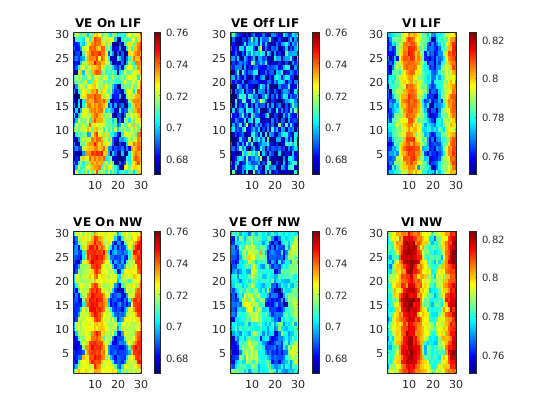

figure
subplot 231
ShowField(mVEOnLIF, 1:900, 30, 30)
title('VE On LIF')
caxis([0.67 0.76])
subplot 232
ShowField(mVEOffLIF, 1:900, 30, 30)
title('VE Off LIF')
caxis([0.67 0.76])
subplot 233
ShowField(mVILIF, 1:900, 30, 30)
title('VI LIF')
caxis([0.75 0.824])
subplot 234
ShowField(mVEOnPixVec, 1:900, 30, 30)
title('VE On NW')
caxis([0.67 0.76])
subplot 235
ShowField(mVEOffPixVec , 1:900, 30, 30)
caxis([0.67 0.76])
title('VE Off NW')
subplot 236
ShowField(mVIPixVec , 1:900, 30, 30)
caxis([0.75 0.824])
title('VI NW')